# Expand Example 3.2:

This live script is for use with the textbook

*Continuous-Time Signals and Systems: A MATLAB Integrated Approach*

by Oktay Alkin, CRC Press, 2025.

Consider the signal $x(t)$ shown below.

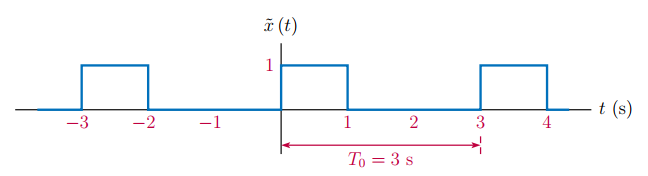

TFS coefficients of the signal are

$a_{0}=\frac{1}{3}$,    $a_{k} = \frac{\sin(2\pi k/3)}{\pi k}$,    $b_{k}=\frac{1-\cos(2\pi k/3)}{\pi k}$

a0 = 1/3;          % Set the dc term
% Set TFS coefficients
k = [1:30];
ak = sin(2*pi*k/3)./(pi*k);
bk = (1-cos(2*pi*k/3))./(pi*k);
t = [-6:0.01:6];   % Vector of time instants
omg0 = 2*pi/3;     % Fundamental frequency

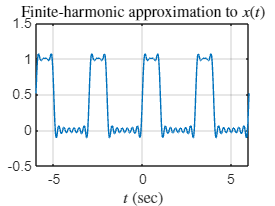

M = 10; % Number of harmonics to include in approximation
%
xtilde = a0;
for kk=1:M
  xtilde = xtilde+ak(kk)*cos(kk*omg0*t)+bk(kk)*sin(kk*omg0*t);  
end
plot(t,xtilde); grid;
axis([-6,6,-0.5,1.5]);
set(0,'defaultTextInterpreter','latex');
xlabel('$t$ (sec)');
title('Finite-harmonic approximation to $x(t)$');

set(0,'defaultTextInterpreter','tex');